# **Discrete SEIR model for vector-borne diseases with a delay in Aquatic population**

**Human population:**


$$H_s (t + 1) = H_s(t)(1-\beta_{mh}\phi_m(t) )(1  -  \mu_h) + N_H  \mu_h\\
H_i (t + 1) =H_s (t)\beta_{mh} \phi_m(t) (1 - \mu_h) + H_i(t) (1 -\gamma) (1 - \mu_h)\\
H_r(t + 1) = H_r(t)  (1 - \mu_h)  + H_i(t)\gamma (1 - \mu_h) $$


**Mosquitoes population:**


$$M_s (t + 1) = M_s(t) (1-\beta_{hm}\Psi_h(t))(1-\mu_m) + A(t)\\
M_i (t + 1) =  M_s \beta_{hm}\Psi_h(t)  (1 -\mu_m) + M_i(t)(1 -\mu_m )$$


**With the following expressions:**

- **Mosquitoes interaction probability: **$\phi_m(t)=1 - \left[ \frac{H_s(t) - 1}{H_s(t)} \right] ^{zM_i(t)\left[ \frac{H_s(t)}{N_H}\right] }$, with $N_H(t) = H_s(t) + H_i(t) + H_r(t) $

- **Human interaction probability: **$\Psi_h(t) = 1- \left[ \frac{N_H - H_i(t)}{N_H(t)} \right]^{z}$, with $N_M(t) = M_s(t) + M_i(t)$

- **Recruitment expressions: ** 

- **Discrete Ricker:** $A(t) =   rN_M(t-2) \exp\left[ 1 -\frac{ N_M(t)}{C}\right]

$

**Parameters (unit time **$week^{-1}$** ):**

- $z$: number of interactions

- $\gamma$: recovery probability

- $\mu_h$: mortality probability for humans

- $\mu_m$: mortality probability for mosquitoes

- $r$: mosquitoes reproduction rate 

- $C$: Carrying capacity  

- $\beta_{hm}$: Infect probability (human to mosquito)

- $\beta_{mh}$: Infect probability (mosquito to human)

**Extra expressions**

- Muerte instantanea de mosquitos: $M_D(t) = \mu(M_i(t) + M_e(t) + M_s(t))$ 

**Life-table papers**

[https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0229829#pone-0229829-t003](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0229829#pone-0229829-t003)

[https://www.researchgate.net/figure/Life-table-attributes-of-Aedes-aegypti-mosquito-from-the-western-region-of-Saudi-Arabia_tbl1_257985786](https://www.researchgate.net/figure/Life-table-attributes-of-Aedes-aegypti-mosquito-from-the-western-region-of-Saudi-Arabia_tbl1_257985786)

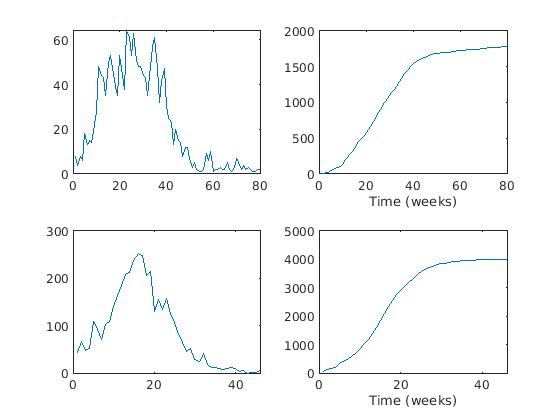

Localities = ["Bello", "Itagui"];
Time = {1:80; 5:50};
Population = [450000; 280000];
ydata = cell(length(Localities),1);
ydataCum = cell(length(Localities),1);
 
for i = 1:length(Localities)
    load('../Data/'+ Localities(i))
    m = Time{i};
    ydata{i} = Cases(m)';
    ydataCum{i} = cumsum(Cases(m))';
end
figure
subplot(2,2,1)
plot(ydata{1})
subplot(2,2,2)
plot(ydataCum{1})
xlabel('Time (weeks)')
subplot(2,2,3)

plot(ydata{2})
subplot(2,2,4)
plot(ydataCum{2})
xlabel('Time (weeks)')

VarNames = {'H_S', 'H_I', 'H_R', 'M_S', 'M_I', 'M_D'};
% VarNames = {'H_S', 'H_I', 'H_R','M_I', 'M_D'};
OutNames = {'H_S', 'H_I', 'H_R', 'M_S', 'M_I', 'M_D', 'H_{I_{ins}}','H_{I_{c}}', 'N_H'};
ParNames = {'\gamma', '\mu_m', '\mu_h', 'z', 'r', 'C', '\beta_mh', '\beta_hm', '\nu_m', '\nu_h'};
FullNames = [VarNames, ParNames];
ModelfncName = 'CHIMERA_Vector';

T_save = cell(length(Localities),1); 

for i = 1:length(Localities)
% for i = 2:2
    RealData = ydata{i};
        
    D = length(RealData);
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    Range1 = [Population(i) Population(i);    %Hs
              RealData(1) RealData(1);       %Hi
              0 0;         %Hr
              10000 500000;    %Ms
              0 100;       %Mi
              0 0          %Md                     
            ];
    
    Range2 = [
              0.1 1;       %gamma 
              0 0.4;       %mu_m
              0 0;         %mu_h
              0 10;        %z
              0 60;        %r 
              1000 250000; %C
              0 1;         %beta_m
              0 1;         %beta_h  
              0 10000;     %nu_m
              0 30000      %nu_h
            ];
    
    RangeT = [Range1; Range2];
    
    
    [T,~] = gsua_dataprep(ModelfncName, RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames);
        
    T.Properties.CustomProperties.Domain = Domain; 
    T.Properties.CustomProperties.output = 7;
    
    T_save{i} = T;
    
    Solver = 'fmincon';
    
    N = 2000; 
    Parameters = [];
    Res = [];
        
    Opt = optimoptions('fmincon','UseParallel', true, 'MaxFunctionEvaluations', 30000, ...
        'MaxIterations', 3000, 'Display','off');
    
%     parfor j = 1:N
%         [T_est, ResTemp] = gsua_pe(T,xdata, RealData,'solver',Solver,'N',1,'opt',Opt,'save',false);
%         Res(j) = ResTemp;
%         Parameters(:,j) = T_est.Estfmincon;
%     end
%     
%     [Res, idx] = sort(Res);
%     Parameters = Parameters(:,idx);     
%     T_save{i}.Nominal = Parameters(:,1);
%     
%     save("ResultsDengue/Estimations_Vector_"+Localities(i)+".mat", "Res",  "Parameters")
%         
%     figure
%     gsua_eval(Parameters(:,1), T_save{i}, xdata, RealData(1,:));
%     suptitle(" residual: " + Res(1) + " Locality:" + Localities{i})
end

Setting environment to work with user-defined function
Setting environment to work with user-defined function


[T,~] = gsua_dataprep(ModelfncName, RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames);

Setting environment to work with user-defined function


outs = 7; 
T.Properties.CustomProperties.output = outs;
T_aux = [];
for k = 1:length(Localities)
    load("ResultsDengue/Estimations_Vector_"+Localities(k)+".mat")
    T_aux = [T_aux, Parameters(:,1)];
end
T.Params = T_aux;
T

T = 11×3 table
                     Range           Nominal              Params         
                ________________    _________    ________________________

    M_S         10000      5e+05     2.55e+05         16096         10000
    M_I             0        100           50       0.92012        4.7616
    \gamma        0.1          1         0.55       0.99959       0.37967
    \mu_m           0        0.4          0.2       0.39887           0.4
    z               0         10            5        9.9742        5.5651
    r               0         60           30       0.13923       0.09702
    C            1000    2.5e+05    1.255e+05    2.1897e+05       2.5e+05
    \beta_mh        0          1          0.5       0.99772       0.95932
    <s

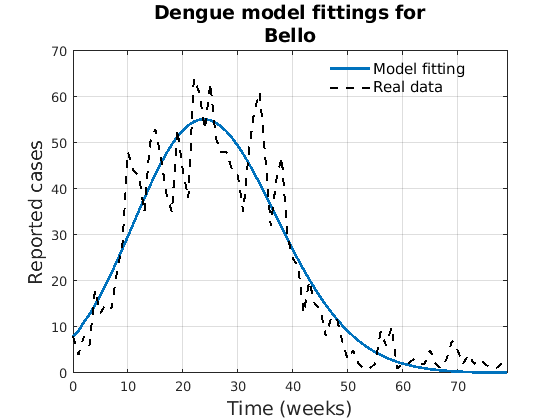

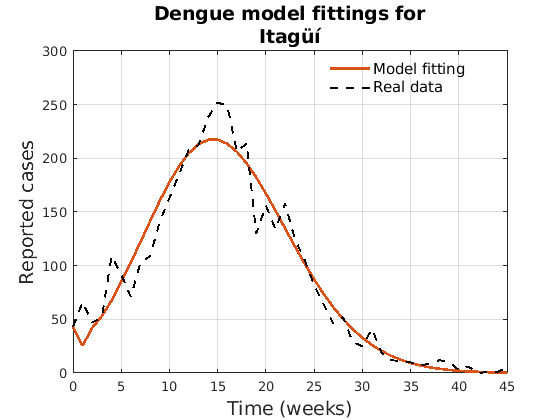

close all

FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/Dengue/";

Titles = ["Model fitting";
         "Real data"];
     
Municipalities = ["Bello", "Itagüí"]; 

for k = 1:length(Localities)
    
    A = rand(2,2);
    cm = colormap(lines(size(A,1)));
   
    RealData = ydata{k};    

    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
  
    load("ResultsDengue/Estimations_Vector_"+Localities(k)+".mat")
    
    T_save{k}.Properties.CustomProperties.output = 7;
    
    ysim = gsua_deval(Parameters(:,1)', T_save{k}, xdata);

    figure   
    plot(xdata, ysim', 'Color', cm(k,:),'LineWidth',2); 
    hold on    
    
    xlim([0 length(RealData)-1]);
    plot(xdata, RealData','--k','LineWidth',1.5)
    
    title(["Dengue model fittings for"; Municipalities(k)],'FontSize',14)
    ylabel("Reported cases",'FontSize',14)
    xlabel("Time (weeks)",'FontSize',14)
    legend(Titles,'Location',"best",'Box','off','FontSize',11)    
    grid on
    
    savefig(FolderFigures + "Fit_Dengue" + Localities(k) + ".fig")
    saveas(gcf,FolderFigures + "Fit_Dengue" + Localities(k) + ".png")
end

## Probabilities vs time

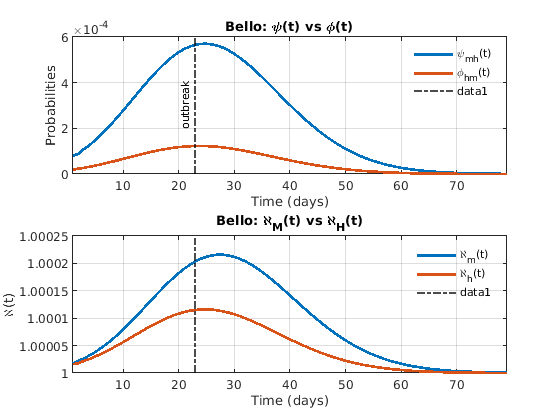

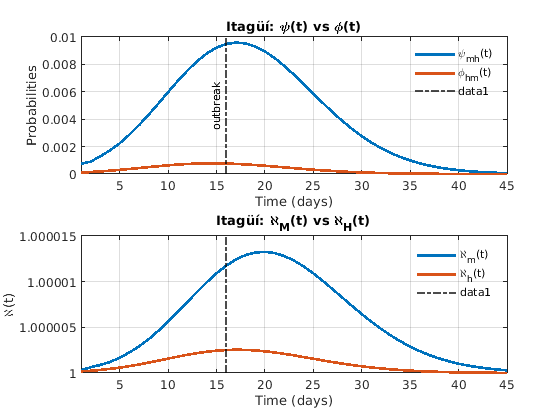

IdxSims = [];
Titles = ["Infected with \psi(t)"; 
    "Infected with \phi(t)";
    "Infected with classic"];
Prob = ["\psi(t)", "\phi(t)", "\chi(t)"];

for k = 1:length(Localities)    
    figure
    counter = 1;

    RealData = ydata{k};    
    MaxValue = find(RealData == max(RealData));
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
        
    load("ResultsDengue/Estimations_Vector_"+Localities(k)+".mat")
    
    T_save{k}.Properties.CustomProperties.output = 10:13;
    ysim = gsua_deval(Parameters(:,1)', T_save{k}, xdata);
     
    [~, Idx] = sort(Res);
       
    subplot(2,1,counter)
        
    plot(squeeze(ysim(1, 2:end))', 'LineWidth',2);           
    hold on    
    plot(squeeze(ysim(2, 2:end))', 'LineWidth',2); 
    grid on
    
    ylabel("Probabilities")  
    xlabel("Time (days)") 
    xlim([1 xdata(end)]);    
    legend("\psi_{mh}(t)","\phi_{hm}(t)","Location","best", "box", "off")
    title(Municipalities(k)+": \psi(t) vs \phi(t)")
    xl = xline(MaxValue,'-.k', {'outbreak'}, "linewidth",1.5);
        xl.LabelVerticalAlignment = 'middle';
        xl.LabelHorizontalAlignment = 'left';
        xl.FontSize = 8;   
    
    subplot(2, 1, counter+1)    
    
    plot(squeeze(ysim(3, 2:end))', 'LineWidth',2); 
    ylabel("\aleph_M(t)")            
    hold on
    
    plot(squeeze(ysim(4, 2:end))', 'LineWidth',2); 
    ylabel("\aleph(t)")
    legend("\aleph_m(t)","\aleph_h(t)", "box", "off")
    grid on
    counter = counter +1;
    xlim([0 length(RealData)]);
    
    title(Municipalities(k)+": \aleph_M(t) vs \aleph_H(t)")
    xlabel("Time (days)") 
    xlim([1 xdata(end)])
    xl = xline(MaxValue,'-.k', "linewidth",1.5);
            xl.LabelVerticalAlignment = 'middle';
            xl.LabelHorizontalAlignment = 'left';
            xl.FontSize = 8;    
    
    counter = counter +1;
    
    savefig(FolderFigures + "Probs_Dengue"+Localities(k)+".fig")
    saveas(gcf,FolderFigures + "Probs_Dengue"+Localities(k)+".png")      
end

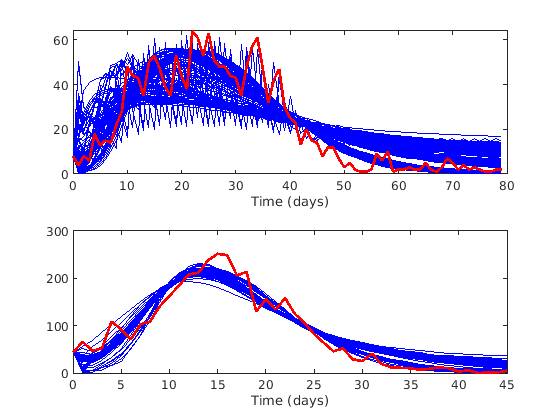

counter = 1;

figure
I = zeros(2,1);

for k = 1:length(Localities)
    
    RealData = ydata{k};
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1; 
    y_sim = [];
    
    load("ResultsDengue/Estimations_Vector_" + Localities(k) + ".mat")
    
    F = find(Res <= min(Res)*5);
    I(counter) = length(F);
    T_save{k}.Properties.CustomProperties.output = 7;
    
    parfor j = 1:length(F)
        y_sim(j,:) = gsua_deval(Parameters(:,j),T_save{k},xdata);
    end
    
    subplot(2,1,counter)
    plot(xdata, y_sim,'b')
    hold on
    plot(xdata,RealData(1,:),'r',"LineWidth",2)
    counter = counter + 1;
    xlabel('Time (days)')

end

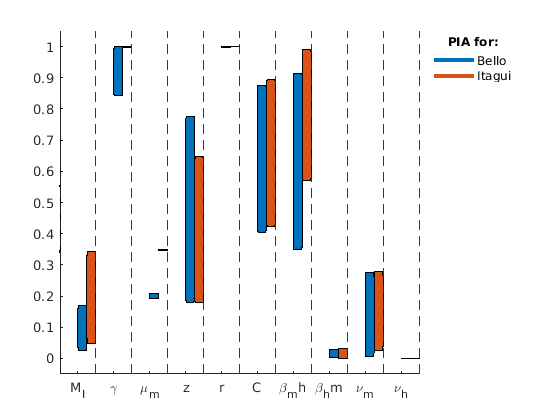

close all
P = [];
counter = 1;
figure 
for k = 1:2
    FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/Dengue/";
    A = rand(3,3);
    cm = colormap(lines(size(A,1)));
    x=[];
    mx=[];
            
        load("ResultsDengue/Estimations_Vector_"+Localities(k)+".mat")
        P = (Parameters(:,1:I(counter))-T_save{k}.Range(:,1))./(T_save{k}.Range(:,2)-T_save{k}.Range(:,1));
        

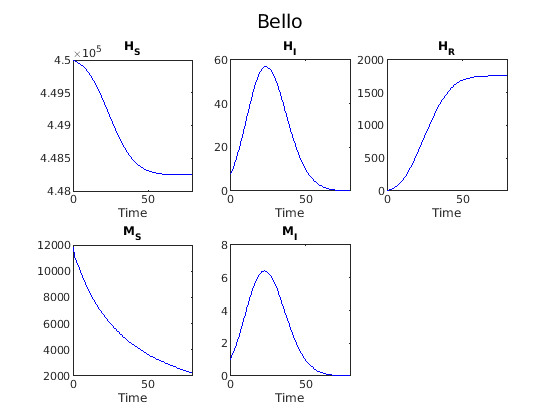

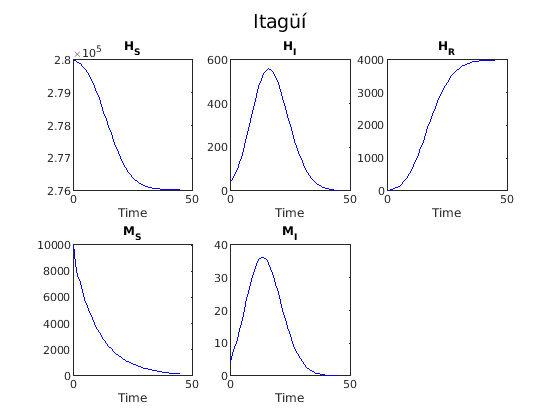

        for j = 1:11
            Pq = rmoutliers(P(j,:),'percentiles', [10 90]);
            Pq = quantile(Pq',[0.25 0.75])';
        %         Pq = [min(Pq) max(Pq)]';
            rectangle('Position',[j+0.25*(k-1) Pq(1) 1/4 Pq(2)-Pq(1)],'FaceColor',[cm(k,:),0.5],'Curvature',0.2);

            hold on
        %         text(0,j+0.75,string(T_save{k, i}.Properties.RowNames(j)))
            x(j) = j+0.5;
            H = xline(x(j),'--');
            if j>1
                mx(j) = x(j-1)+(x(j)-x(j-1))/2;
            else
            mx(j) = (x(j)+1)/2;
            end
        end
        counter = counter + 1;
end

h1 = plot(-100, -110,'color', cm(1,:),"LineWidth",3);
h2 = plot(-100, -110,'color', cm(2,:),"LineWidth",3);
      
lgd = legend([h1; h2],"Bello", "Itagui", "box",'off','Location',"bestoutside");
title(lgd,'PIA for:')

xlim([min(x) max(x)])
ylim([-0.05 1.05])
xticks(mx)
set(gca,'XTickLabel',T_save{k}.Properties.RowNames,'TickLabelInterpreter', 'tex')


savefig(FolderFigures + "PIA_Dengue.fig")
saveas(gcf,FolderFigures + "PIA_Dengue.png")

for k = 1:length(Localities)
    counter = 1;
    RealData = ydata{k};    
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    figure        
        load("ResultsDengue/Estimations_Vector_"+Localities(k)+".mat")
        N = size(Res, 2);
        ysim = zeros(N, 2, D);
        T_save{k}.Properties.CustomProperties.output = 1:5;
        figure
        gsua_eval(Parameters(:,1), T_save{k}, xdata);
        suptitle(Municipalities(k))
end